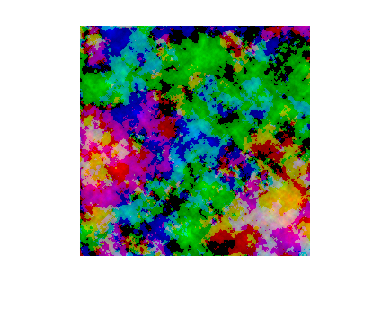

clear
seed = 509511538;
rng(seed);

size_rec = 64; %ширина полоски освещения в пикселях
scale = 4; %ширина саб-пикселя
map_size = size_rec*scale; %ширина конвеера в пикселях
tr1 = false(map_size);
tr2 = false(map_size);
tr3 = false(map_size);

a = hadamard(size_rec)>0; %создание матрицы Адмара
% for i = 1:size_rec
%     a1 = randi(2,sqrt(size_rec))-1;
%     a(:,i) = reshape(a1,1,[])';
% end
I_h = imresize(a,scale,'nearest'); %увеличение размеров матрицы с учетом саб-пикселя

n = map_size; %ширина образца
m = map_size; %длина образца
im = perlin_noise(n,m);
im(im<0)=0;
im=im/max(max(im));
im=(im>0)+im;
im1=im/max(max(im));

im = perlin_noise(n,m);
im(im<0)=0;
im=im/max(max(im));
im=(im>0)+im;
im2=im/max(max(im));

im = perlin_noise(n,m);
im(im<0)=0;
im=im/max(max(im));
im=(im>0)+im;
im3=im/max(max(im));

im_t(:,:,1) = im1;
im_t(:,:,2) = im2;
im_t(:,:,3) = im3;

imshow(im_t);



step_wait = 16; %сколько линий успевают осветить объект за время перемещения на 1 пиксель
N = (map_size/step_wait)*5;

k=0;
I = false(map_size);
for j = 1:N
    sBI1 = zeros(1,size_rec);
    sI1 = sBI1;
    sB1 = 0;
    sBI2 = zeros(1,size_rec);
    sI2 = sBI2;
    sB2 = 0;
    sBI3 = zeros(1,size_rec);
    sI3 = sBI3;
    sB3 = 0;
    for i = 1:size_rec
        if mod(i,step_wait) == 0 || i == 1
            if k<map_size
                k=k+1;
                tr1(:,1:(k)) = im1(:,end-(k-1):end);
                tr2(:,1:(k)) = im2(:,end-(k-1):end);
                tr3(:,1:(k)) = im3(:,end-(k-1):end);
            elseif k<2*map_size
                k=k+1;
                tr1(:,1:k-map_size) = 0;
                tr1(:,k-map_size:end) = im1(:,1:2*map_size-k+1);
                tr2(:,1:k-map_size) = 0;
                tr2(:,k-map_size:end) = im2(:,1:2*map_size-k+1);
                tr3(:,1:k-map_size) = 0;
                tr3(:,k-map_size:end) = im3(:,1:2*map_size-k+1);
            end
        end
        I(:,map_size/2-2:map_size/2+1) = I_h(:,rem(1+(i-1)*scale,map_size):rem(1+(i-1)*scale,map_size)+3);

        B1 = sum(sum(I.*tr1));
        sBI1 = sBI1 + B1 .* a(i,:);
        sI1 = sI1 + a(i,:);
        sB1 = sB1 + B1;

        B2 = sum(sum(I.*tr2));
        sBI2 = sBI2 + B2 .* a(i,:);
        sI2 = sI2 + a(i,:);
        sB2 = sB2 + B2;

        B3 = sum(sum(I.*tr3));
        sBI3 = sBI3 + B3 .* a(i,:);
        sI3 = sI3 + a(i,:);
        sB3 = sB3 + B3;
    end
    G = sBI1 ./ i - (sB1 / i ) .* (sI1 ./ i);
    if sum(sum(G))>0
        G = G - min(min(G));
        G = G/max(max(G));
    end
    G_1(:,j) = G';
    G = sBI2 ./ i - (sB2 / i ) .* (sI2 ./ i);
    if sum(sum(G))>0
        G = G - min(min(G));
        G = G/max(max(G));
    end
    G_2(:,j) = G';
    G = sBI3 ./ i - (sB3 / i ) .* (sI3 ./ i);
    if sum(sum(G))>0
        G = G - min(min(G));
        G = G/max(max(G));
    end
    G_3(:,j) = G';
end

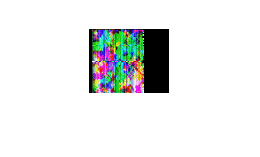

% G_1 = G_1 - min(min(G_1));
% G_2 = G_2 - min(min(G_2));
% G_3 = G_3 - min(min(G_3));
% G_1 = G_1/max(max(G_1));
% G_2 = G_2/max(max(G_2));
% G_3 = G_3/max(max(G_3));
G_c(:,:,1) = G_1;
G_c(:,:,2) = G_2;
G_c(:,:,3) = G_3;
imshow(flip(G_c,2),[]);

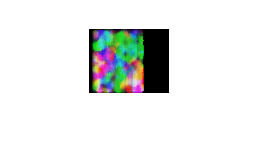


G_c_m(:,:,1) = medfilt2(G_1,[5 5]);
G_c_m(:,:,2) = medfilt2(G_2,[5 5]);
G_c_m(:,:,3) = medfilt2(G_3,[5 5]);
imshow(flip(G_c_m,2),[]);